Industrial AI Predictive Maintenance System

Phase 1: Data Exploration

Objective:

Load the AI4I 2020 Predictive Maintenance dataset and understand the machine sensor data before training machine learning models.

Author:

Vusi Romeo Mtsweni

date: 17 July 2026

%% Initialize Workspace

clc
clear
close all

%% Load Dataset

[file, path] = uigetfile('*.csv', 'Select the AI4I Dataset');

machineData = readtable(fullfile(path, file));


disp("Dataset Loaded Successfully!")

Dataset Loaded Successfully!



head(machineData)

    UDI    ProductID     Type     AirTemperature_K_    ProcessTemperature_K_    RotationalSpeed_rpm_    Torque_Nm_    ToolWear_min_    MachineFailure    TWF    HDF    PWF    OSF    RNF
    ___    __________    _____    _________________    _____________________    ____________________    __________    _____________    ______________    ___    ___    ___    ___    ___

     1     {'M14860'}    {'M'}          298.1                  308.6                    1551               42.8             0                0           

%% Dataset Information

size(machineData)

ans =        10000          14



summary(machineData)


machineData: 10000×14 table

Variables:

    UDI: double (UDI)
    ProductID: cell array of character vectors (Product ID)
    Type: cell array of character vectors (Type)
    AirTemperature_K_: double (Air temperature [K])
    ProcessTemperature_K_: double (Process temperature [K])
    RotationalSpeed_rpm_: double (Rotational speed [rpm])
    Torque_Nm_: double (Torque [Nm])
    ToolWear_min_: double (Tool wear [min])
    MachineFailure: double (Machine failure)
    TWF: double (TWF)
    HDF: double (HDF)
    PWF: double (PWF)
    OSF: double (OSF)
    RNF: double (RNF)

Statistics for applicable variables:

                             NumMissing        Min             Median       


machineData.Properties.VariableNames

ans = 1×14 cell array
    {'UDI'}    {'ProductID'}    {'Type'}    {'AirTemperature_K_'}    {'ProcessTemperature_K_'}    {'RotationalSpeed_rpm_'}    {'Torque_Nm_'}    {'ToolWear_min_'}    {'MachineFailure'}    {'TWF'}    {'HDF'}    {'PWF'}    {'OSF'}    {'RNF'}


%% Missing Values

missingValues = sum(ismissing(machineData))

missingValues =      0     0     0     0     0     0     0     0     0     0     0     0     0     0



disp("Total Missing Values:")

Total Missing Values:



disp(missingValues)

     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%% First Ten Records

machineData(1:10,:)

ans = 10×14 table
    UDI    ProductID     Type     AirTemperature_K_    ProcessTemperature_K_    RotationalSpeed_rpm_    Torque_Nm_    ToolWear_min_    MachineFailure    TWF    HDF    PWF    OSF    RNF
    ___    __________    _____    _________________    _____________________    ____________________    __________    _____________    ______________    ___    ___    ___    ___    ___

     1     {'M14860'}    {'M'}          298.1                  308.6                    1551               42.8             0          

%% Machine Failure Count

failureCounts = groupcounts(machineData,"MachineFailure")

failureCounts = 2×3 table
    MachineFailure    GroupCount    Percent
    ______________    __________    _______

          0              9661        96.61 
          1               339         3.39 

	Get insights using Copilot



disp(failureCounts)

    MachineFailure    GroupCount    Percent
    ______________    __________    _______

          0              9661        96.61 
          1               339         3.39 



%% Dataset Dimensions

[numRows, numCols] = size(machineData);

fprintf("Number of samples : %d\n", numRows);

Number of samples : 10000


fprintf("Number of features: %d\n", numCols);

Number of features: 14


%% Statistical Summary

disp("Numerical Statistics")

Numerical Statistics



summary(machineData)


machineData: 10000×14 table

Variables:

    UDI: double (UDI)
    ProductID: cell array of character vectors (Product ID)
    Type: cell array of character vectors (Type)
    AirTemperature_K_: double (Air temperature [K])
    ProcessTemperature_K_: double (Process temperature [K])
    RotationalSpeed_rpm_: double (Rotational speed [rpm])
    Torque_Nm_: double (Torque [Nm])
    ToolWear_min_: double (Tool wear [min])
    MachineFailure: double (Machine failure)
    TWF: double (TWF)
    HDF: double (HDF)
    PWF: double (PWF)
    OSF: double (OSF)
    RNF: double (RNF)

Statistics for applicable variables:

                             NumMissing        Min             Median       

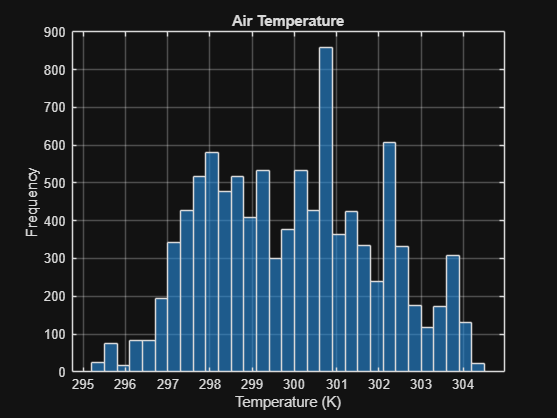

%% Air Temperature

figure

histogram(machineData.AirTemperature_K_)

title("Air Temperature")

xlabel("Temperature (K)")

ylabel("Frequency")

grid on

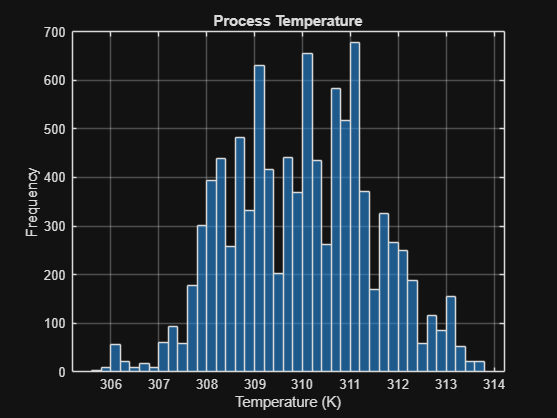

%% Process Temperature

figure

histogram(machineData.ProcessTemperature_K_)

title("Process Temperature")

xlabel("Temperature (K)")

ylabel("Frequency")

grid on

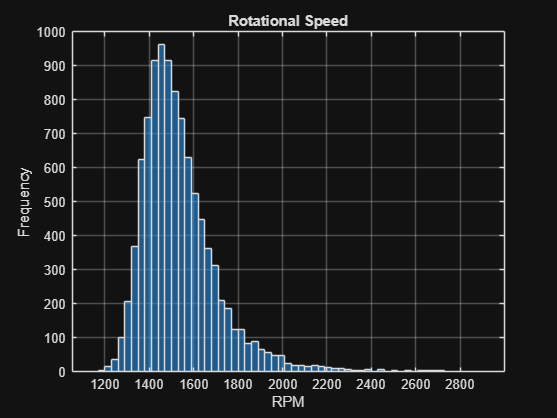

%% Rotational Speed

figure

histogram(machineData.RotationalSpeed_rpm_)

title("Rotational Speed")

xlabel("RPM")

ylabel("Frequency")

grid on

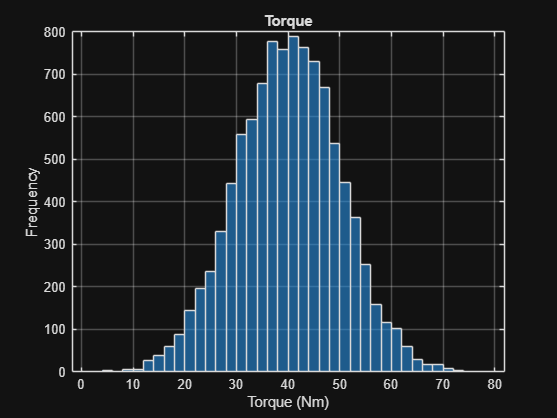

%% Torque

figure

histogram(machineData.Torque_Nm_)

title("Torque")

xlabel("Torque (Nm)")

ylabel("Frequency")

grid on

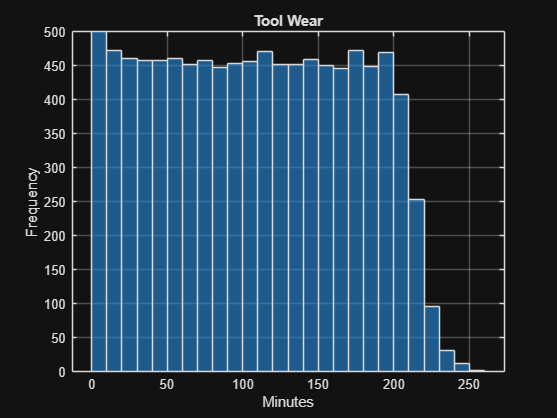

%% Tool Wear

figure

histogram(machineData.ToolWear_min_)

title("Tool Wear")

xlabel("Minutes")

ylabel("Frequency")

grid on

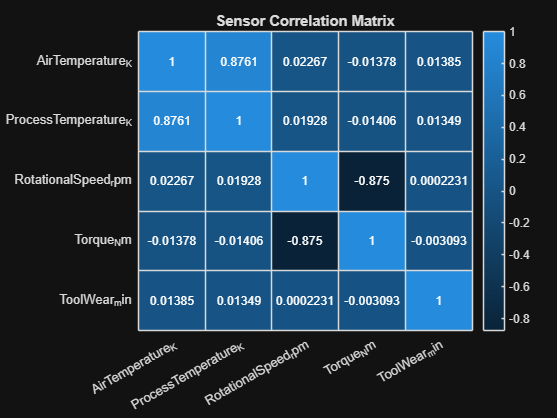

%% Correlation Matrix

numericData = machineData(:, ...
    ["AirTemperature_K_", ...
    "ProcessTemperature_K_", ...
    "RotationalSpeed_rpm_", ...
    "Torque_Nm_", ...
    "ToolWear_min_"]);

corrMatrix = corr(table2array(numericData));

figure

heatmap(numericData.Properties.VariableNames,...
    numericData.Properties.VariableNames,...
    corrMatrix)

title("Sensor Correlation Matrix")

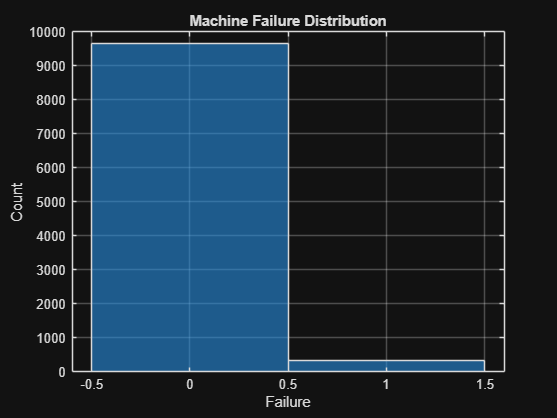

%% Machine Failure Distribution

figure

histogram(machineData.MachineFailure)

title("Machine Failure Distribution")

xlabel("Failure")

ylabel("Count")

grid on

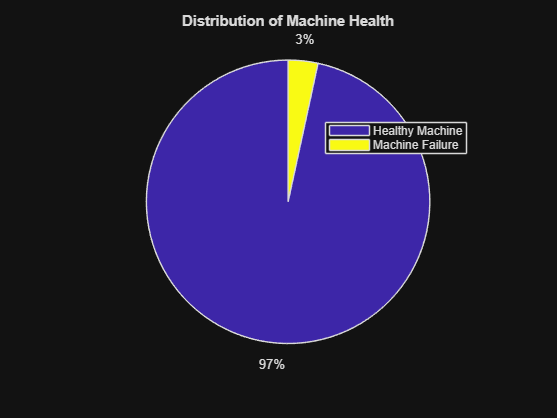

%% Machine Health Distribution

failureTable = groupcounts(machineData,"MachineFailure");

figure

pie(failureTable.GroupCount)

legend("Healthy Machine","Machine Failure","Location","best")

title("Distribution of Machine Health")

colormap(parula)

%% Select Features

X = machineData(:, ...
    ["AirTemperature_K_", ...
    "ProcessTemperature_K_", ...
    "RotationalSpeed_rpm_", ...
    "Torque_Nm_", ...
    "ToolWear_min_"]);

Y = machineData.MachineFailure;

%% Split Dataset

cv = cvpartition(Y,'HoldOut',0.30);

XTrain = X(training(cv),:);
XTest  = X(test(cv),:);

YTrain = Y(training(cv));
YTest  = Y(test(cv));

disp("Dataset Split Complete")

Dataset Split Complete


%% Train Decision Tree

decisionTreeModel = fitctree(XTrain,YTrain);

disp("Decision Tree Trained Successfully!")

Decision Tree Trained Successfully!


%% Predictions

YPred = predict(decisionTreeModel,XTest);

%% Accuracy

accuracy = mean(YPred == YTest) * 100;

fprintf("Model Accuracy = %.2f %%\n", accuracy);

Model Accuracy = 98.10 %


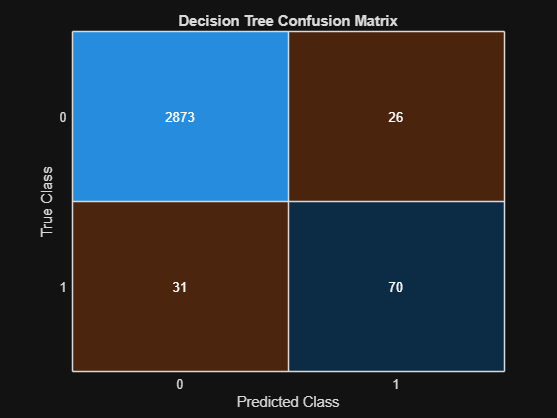

%% Confusion Matrix

figure

confusionchart(YTest,YPred)

title("Decision Tree Confusion Matrix")

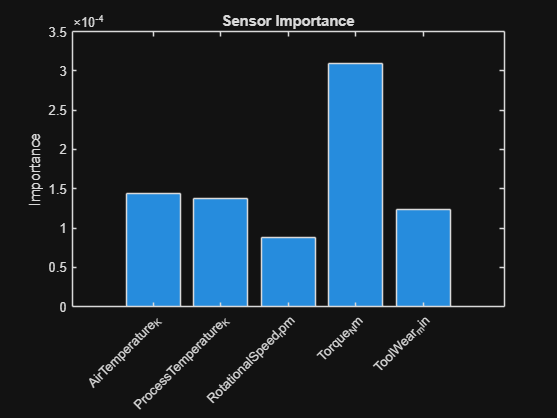

%% Feature Importance

importance = predictorImportance(decisionTreeModel);

figure

bar(importance)

xticklabels(X.Properties.VariableNames)

xtickangle(45)

ylabel("Importance")

title("Sensor Importance")

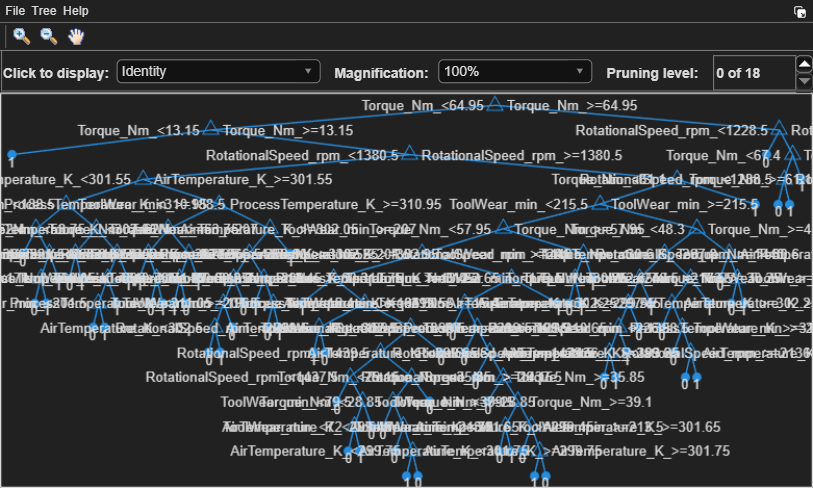

%% Decision Tree Visualization

view(decisionTreeModel,"Mode","graph")